%% Individual Assignment — Image Processing Fundamentals

%
% Option A asks which of three fixed denoising methods best restores
% rice.png after Gaussian noise and salt-and-pepper noise are added.

clear;
close all;
clc;

scriptFolder = fileparts(mfilename('fullpath'));
if isempty(scriptFolder)
    scriptFolder = pwd;
end

resultsFolder = fullfile(scriptFolder, 'results');
if ~isfolder(resultsFolder)
    mkdir(resultsFolder);
end

matlabRelease = version('-release');
fprintf('MATLAB R%s\n', matlabRelease);

MATLAB R2026b



%% Reference image and controlled degradation
% Keep rice.png in its original class. Generate the degraded image once
% and use the same image as the input to all three filtering methods.

Iref = imread('rice.png');
rng(42);
Id = imnoise(imnoise(Iref,'gaussian',0,0.01),'salt & pepper',0.02);

%% Apply the three filters
% The median filter removes isolated extreme values. Gaussian smoothing
% reduces random fluctuations but can soften grain boundaries. The
% combined method applies median filtering first, then Gaussian smoothing.
% All unspecified filter settings use MATLAB defaults.

I_median = medfilt2(Id, [3 3]);
I_gaussian = imgaussfilt(Id, 1.5);
I_combined = imgaussfilt(I_median, 1);

imwrite(I_median, fullfile(resultsFolder, 'median_3x3.png'));
imwrite(I_gaussian, fullfile(resultsFolder, 'gaussian_sigma_1_5.png'));
imwrite(I_combined, fullfile(resultsFolder, 'median_then_gaussian.png'));

%% Compare PSNR and SSIM against rice.png
% Higher PSNR indicates lower pixel error. Higher SSIM indicates greater
% structural similarity to the reference. The degraded image is included
% as a baseline. The measurements use the full image.

methods = ["Degraded baseline"; "Median 3 x 3"; ...
    "Gaussian, sigma 1.5"; "Median then Gaussian, sigma 1"];
images = {Id, I_median, I_gaussian, I_combined};

psnrValues = zeros(numel(images), 1);
ssimValues = zeros(numel(images), 1);

for k = 1:numel(images)
    psnrValues(k) = psnr(images{k}, Iref);
    ssimValues(k) = ssim(images{k}, Iref);
end

scores = table(methods, psnrValues, ssimValues, ...
    'VariableNames', {'Method', 'PSNR_dB', 'SSIM'});
disp(scores);

                Method                 PSNR_dB     SSIM  
    _______________________________    _______    _______

    "Degraded baseline"                18.088     0.36958
    "Median 3 x 3"                      25.37     0.62323
    "Gaussian, sigma 1.5"              25.755     0.69213
    "Median then Gaussian, sigma 1"    26.368     0.70515



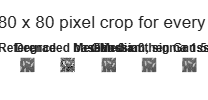

writetable(scores, fullfile(resultsFolder, 'metrics.csv'));

%% Compare the same 80-by-80-pixel region
% Each panel uses rows 90–169 and columns 90–169. Compare dark and bright
% specks, background graininess, and the sharpness of rice boundaries.

rows = 90:169;
cols = 90:169;
comparisonImages = [{Iref}, images];
labels = ["Reference"; methods];

fig = figure('Color', 'white', 'Position', [100 100 1100 300]);
layout = tiledlayout(1, 5, 'TileSpacing', 'compact', 'Padding', 'compact');

for k = 1:numel(comparisonImages)
    nexttile;
    imshow(comparisonImages{k}(rows, cols));
    title(labels(k), 'Interpreter', 'none', 'FontSize', 9);
end

title(layout, 'Same 80 x 80 pixel crop for every method');
exportgraphics(layout, fullfile(resultsFolder, 'zoom_comparison.png'), ...
    'Resolution', 200);


%% Interpret the measured results
% Rank the three filtered images. The provisional preference uses SSIM
% because this comparison prioritizes preserving rice-grain structure.
% Verify the preference by inspecting the zoomed grain boundaries.

[~, psnrIndex] = max(psnrValues(2:end));
[~, ssimIndex] = max(ssimValues(2:end));
bestPSNR = psnrIndex + 1;
bestSSIM = ssimIndex + 1;

fprintf('Highest PSNR: %s (%.2f dB)\n', ...
    char(methods(bestPSNR)), psnrValues(bestPSNR));

Highest PSNR: Median then Gaussian, sigma 1 (26.37 dB)


fprintf('Highest SSIM: %s (%.4f)\n', ...
    char(methods(bestSSIM)), ssimValues(bestSSIM));

Highest SSIM: Median then Gaussian, sigma 1 (0.7051)



fprintf(['My metric-based preference is %s because it has the highest SSIM.\n' ...
    'The crop helps check whether this choice leaves specks or softens grain edges.\n' ...
    'A limitation is that the comparison uses one image and one synthetic noise realization.\n'], ...
    char(methods(bestSSIM)));

My metric-based preference is Median then Gaussian, sigma 1 because it has the highest SSIM.
The crop helps check whether this choice leaves specks or softens grain edges.
A limitation is that the comparison uses one image and one synthetic noise realization.



%% Generate the GitHub README with measured scores
readmePath = fullfile(scriptFolder, 'README.md');
fid = fopen(readmePath, 'w');
assert(fid ~= -1, 'Could not write README.md.');

fprintf(fid, '# Image Processing Fundamentals - Option A\n\n');
fprintf(fid, '**Mahir Foysol Chowdhury**\n\n');
fprintf(fid, '## Question\n\n');
fprintf(fid, ['Which fixed denoising method best restores the MATLAB sample ' ...
    'image \`rice.png\` after Gaussian and salt-and-pepper noise?\n\n']);


fprintf(fid, '## Reproduce the experiment\n\n');
fprintf(fid, ['Open \`analysis.mlx\` in MATLAB R%s with Image Processing ' ...
    'Toolbox and click **Run**. MATLAB provides \`rice.png\`.\n\n'], matlabRelease);

fprintf(fid, ['The noise was generated once using seed 42, Gaussian mean 0 ' ...
    'and variance 0.01, followed by salt-and-pepper noise with density 0.02. ' ...
    'The filters were a 3 x 3 median, Gaussian with sigma 1.5, and ' ...
    '3 x 3 median followed by Gaussian with sigma 1. Other settings used MATLAB defaults.\n\n']);

fprintf(fid, '## Results\n\n');
fprintf(fid, '| Method | PSNR (dB) | SSIM |\n|---|---:|---:|\n');
for k = 1:numel(methods)
    fprintf(fid, '| %s | %.2f | %.4f |\n', ...
        char(methods(k)), psnrValues(k), ssimValues(k));
end

fprintf(fid, '\n![Same 80 x 80 crop for all methods](results/zoom_comparison.png)\n\n');
fprintf(fid, '## Conclusion and limitation\n\n');
fprintf(fid, ['%s achieved the highest PSNR (%.2f dB). ' ...
    '%s achieved the highest SSIM (%.4f) and is my metric-based preference ' ...
    'because preserving grain structure is the priority in this comparison. ' ...
    'The experiment uses one reference image and one synthetic noise realization, ' ...
    'so the same ranking may change with another image or noise level.\n\n'], ...
    char(methods(bestPSNR)), psnrValues(bestPSNR), ...
    char(methods(bestSSIM)), ssimValues(bestSSIM));

fprintf(fid, '## AI assistance\n\n');
fprintf(fid, ['I used ChatGPT to help draft the MATLAB code, structure the ' ...
    'comparison, and generate the README.\n']);
fclose(fid);